# This script will help you test out your kNN code

## Select which data to use:

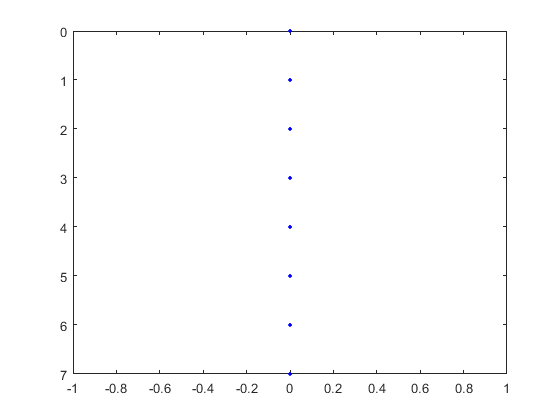

% 1 = dot cloud 1
% 2 = dot cloud 2
% 3 = dot cloud 3
% 4 = OCR data

dataSetNr = 4; % Change this to load new data 

% X - Data samples
% D - Desired output from classifier for each sample
% L - Labels for each sample
[X, D, L] = loadDataSet( dataSetNr );

% You can plot and study dataset 1 to 3 by running:
plotCase(X,D)

## Select a subset of the training samples

numBins = 5;                    % Number of bins you want to devide your data into
numSamplesPerLabelPerBin = inf; % Number of samples per label per bin, set to inf for max number (total number is numLabels*numSamplesPerBin)
selectAtRandom = true;          % true = select samples at random, false = select the first features

[XBins, DBins, LBins] = selectTrainingSamples(X, D, L, numSamplesPerLabelPerBin, numBins, selectAtRandom);

% Note: XBins, DBins, LBins will be cell arrays, to extract a single bin from them use e.g.
% XBin1 = XBins{1};
%
% Or use the combineBins helper function to combine several bins into one matrix (good for cross validataion)
% XBinComb = combineBins(XBins, [1,2,3]);

% Add your own code to setup data for training and test here
XTrain = combineBins(XBins, 1:numBins-1);
LTrain = combineBins(LBins, 1:numBins-1);
XTest  = XBins{numBins};
LTest  = LBins{numBins};

## Use kNN to classify data

% Set the number of neighbors
minK = 1;
maxK = 12;
k = findK(XTrain, XVal, LTrain, LVal, minK, maxK)

k = 1



% Classify training data
LPredTrain = kNN(XTrain, k, XTrain, LTrain);
% Classify test data
LPredTest  = kNN(XTest , k, XTrain, LTrain);

## Calculate The Confusion Matrix and the Accuracy

% The confucionMatrix
cM = calcConfusionMatrix(LPredTest, LTest)

cM =    110     0     0     0     0     0     0     0     0     0
     0   109     0     0     0     0     0     1     0     0
     0     0   110     0     0     0     0     0     0     0
     0     0     0   109     0     0     0     0     0     1
     0     0     0     0   108     0     0     1     0     1
     0     0     0     0     0   109     0     0     0     1
     0     0     0     0     0     0   110     0     0     0
     0     1     0     0     0     0     0   108     0     1
     0     1     0     0     0     0     0     0   107     2
     0     0     0     0     1     1     0     0     0   108



% The accuracy
acc = calcAccuracy(cM)

acc = 0.9891

## Plot classifications

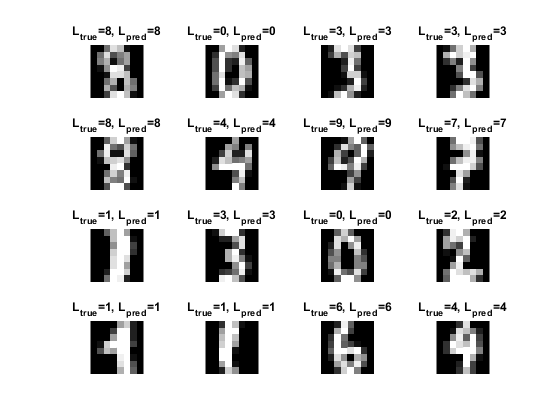

if dataSetNr < 4
    plotResultDots(XTrain, LTrain, LPredTrain, XTest, LTest, LPredTest, 'kNN', [], k);
else
    plotResultsOCR(XTest, LTest, LPredTest)
end